# Trabajo 3 - Teoría de las telecomunicaciones 1

**Universidad del Cauca - 2021-1**

**Grupo A12 - Nicolás Chicaiza y Nicolás Zambrano**

### 1. GRAFICA DE SEÑAL ASIGNADA

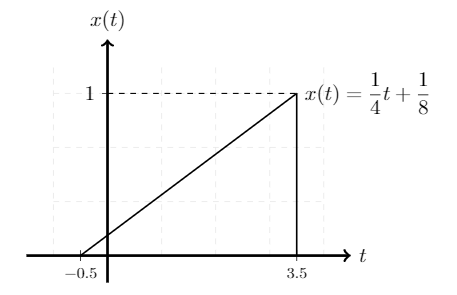

### 2. MODIFICACION DE PARAMETROS 


clear; %Limpio Espacio de trabajo
clc;

A=1; %Amplitud rampa (Multiplicacion por un escalar)
sh=0.5; %Desplazamiento en el tiempo (Normalizado solo para valores positivos)
T=4; %Periodo rampa (Igual al taller 1)
esc=1; %Cambio de Escala
shf=0; %Desplazamiento en frecuencia
np=0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
fs=1/(T*np); %Frecuencia de muestreo
t=-(T+sh):np*T:(T+sh); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


ramp=(A/T)*((t*esc)+sh); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls(((t*esc)+sh)-(T/2),(T)); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
ps=ps.*exp(i*2*pi*shf*t);

### 3. CALCULO DE TRANSFORMADA DE FOURIER (SIMBOLICA)

Verificación de cálculos

%---------------------------Transformada pulso rampa--------------------------
syms x f;
dif=((A/T)*(((x*esc)+sh))*exp(i*2*pi*shf*x)*exp(-i*2*pi*f*x)); %Expresion dentro de la integral de la transformada de Fourier
trfu=int(dif,[(0-sh)/esc (T-sh)/esc]) %Integral definida en el periodo de la rampa

$$trfu = \frac{{\mathrm{e}}^{-7\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right)}{16\,f^{2}\,\pi^{2}}$$

trfum=simplify(abs(trfu))

$$trfum = \frac{{\mathrm{e}}^{7\,\pi \,\mathrm{imag}\left(f\right)}\,\left|1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right|}{16\,\pi^{2}\,{\left|f\right|}^{2}}$$

%trfua=simplify(angle(trfu))
double(limit(trfum))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC

ans = 2

double(simplify(abs(limit(trfum,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1

ans = 0.1592

### 4. TRANSFORMADA DE FOURIER DESDE LA EXPRESION (SIMBOLICA)

%---------------------------TF Simbolica--------------------------
tic
Pts=1000;%Numero de muestras a evaluar en la ecuacion simbolica
fsimb=linspace(-3,3,Pts);
Xfsimb=linspace(0,0,Pts);
Afsimb=linspace(0,0,Pts);
for(n=1:length(fsimb))
    if(fsimb(n)==shf) %Condicional para evitar la indeterminacion de la expresion simbolica en f=shf
        Xfsimb(n)=limit(trfum,f,fsimb(n))
    else
        Xfsimb(n)=subs(trfum,f,fsimb(n));
    end
    %Afsimb(n)=subs(trfua,f,fsimb(n));
end
tiesimbolica=toc

tiesimbolica = 23.9919

### 5. CONSTRUCCIÓN FILTRO IDEAL PASA BAJAS

sym f

$$ans = f$$

flp = t

flp =    -4.5000   -4.4960   -4.4920   -4.4880   -4.4840   -4.4800   -4.4760   -4.4720   -4.4680   -4.4640   -4.4600   -4.4560   -4.4520   -4.4480   -4.4440   -4.4400   -4.4360   -4.4320   -4.4280   -4.4240   -4.4200   -4.4160   -4.4120   -4.4080   -4.4040   -4.4000   -4.3960   -4.3920   -4.3880   -4.3840   -4.3800   -4.3760   -4.3720   -4.3680   -4.3640   -4.3600   -4.3560   -4.3520   -4.3480   -4.3440   -4.3400   -4.3360   -4.3320   -4.3280   -4.3240   -4.3200   -4.3160   -4.3120   -4.3080   -4.3040


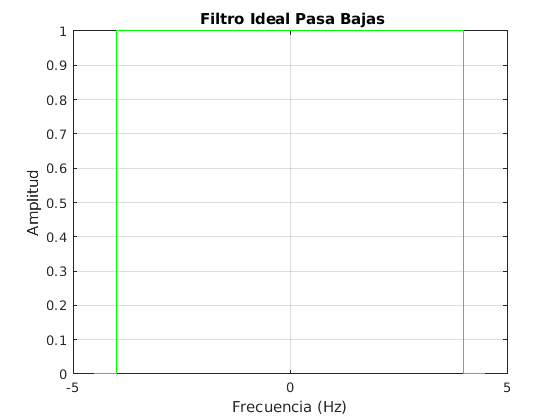

K = 1; % Amplitud del rectangulo
B = 4; % Periodo medio del rectangulo
td = 1; % Tiempo de máxima amplitud en el dominio temporal
hf = K*rectpuls(t,2*B); % Función del filtro ideal en el dominio temporal
plot(flp,hf,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf Filtro Ideal Pasa Bajas');

## 6. Filtrado de la señal

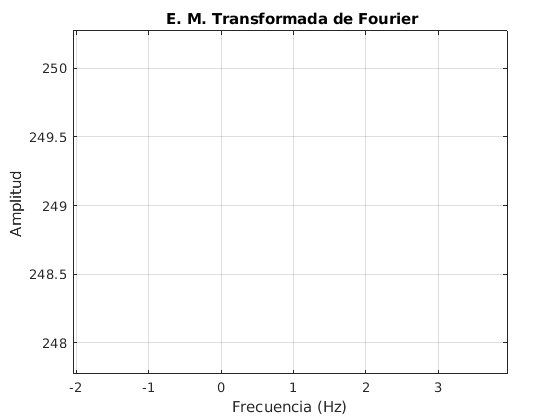

w = conv2(hf,Xfsimb);
f=linspace(-fs/2,fs/2,length(w));

plot(f,abs(w),'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier');

### 6. GRAFICAS DE RESULTADOS

%--------------------Graficacion de Resultados---------------------------
plot(t,abs(ps),'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-5 5]); %Graficacion de Resultados
title('\bf Señal Original');
plot(fsimb,Xfsimb,'black'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier desde Ecuacion Simbolica');
